# LAB 2: Numeric Simulation 

X0 = 10; 

## Fluid Level Example

T = 5; 
fld_lvl_sim(X0, T);

T = 0.1; 
fld_lvl_sim(X0, T);

# EXPERIMENTAL PROCEDURE

## PART 1: SIMULATE SYSTEM WITH LSIM

#### PLEASE MAKE SURE YOU HAVE THE CONTROL SYSTEMS TOOLBOX ALREADY INSTALLED!

Here we simulate the system with three different input signals: square (step), sine, and zero input. In all cases, the initial conditions are the same. 

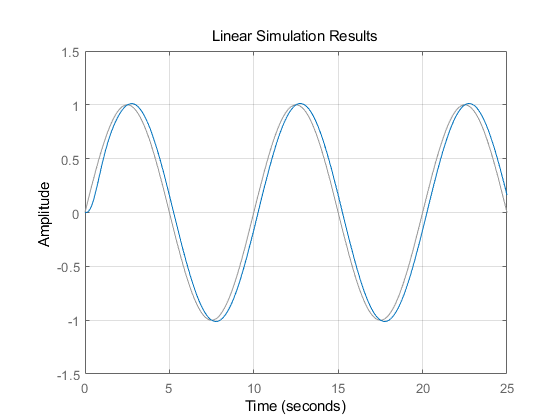


% Define the transfer function of the system
H = tf(16,[1 4 16]);

A = [0,1; -16,-4];
B = [0;16];
C = [1 0];
D = 0;
sys = ss(A,B,C,D); 
x0 = [0,0]; 

% Sinusoidal signal
[u,t] = gensig('sin',10,25,0.01);
%u = zeros(2501, 1); 
% Simulate the system with sinusoidal
lsim(sys,u,t, x0);
grid on;

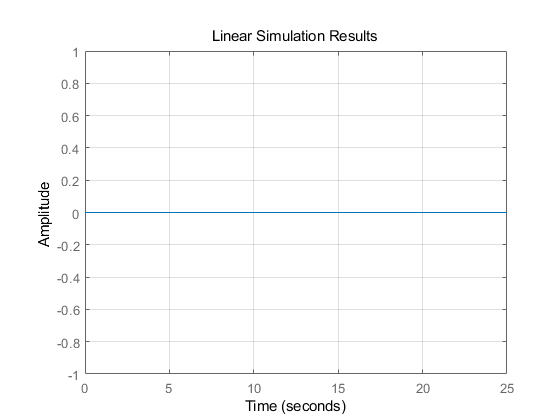


% Zero input 
u = zeros(size(u));  
lsim(sys,u,t, x0);
grid on; 

## PART 2: SIMULATE SYSTEM WITH EULER METHOD


x0 = [3,0]; 
T = 0.01;
% Simulate with sinusoidal signal OR natural response  
% RESP = 0 : Natural 
% RESP = 1 : Sinusoidal


### With natural response (u(t) = 0 )

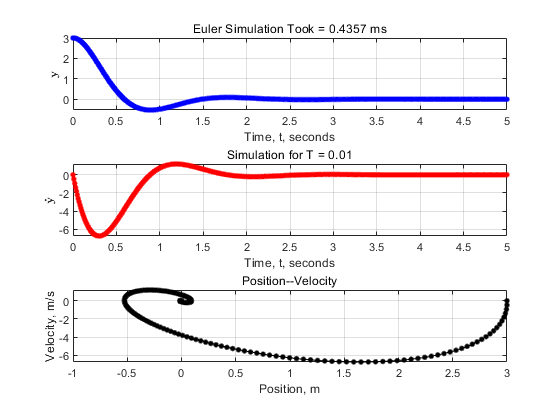

Time elapsed 4.357e-01 ms 
 


RESP = 0; 

N = round(5/T) + 1;
if RESP==0
    u = zeros(N,1);
elseif RESP ==1
[u,~] = gensig('sin',5,10,0.01);
else
    u= 0;
end
figure(2);
clf;
f_sim(x0, T, u, RESP); 

In the figure above, notice that the decay rate, $T_s \approx 2.3$ seconds. This corresponds to $\frac{4.6}{\sigma}$. 

### With u(t) = sin(0.1t)

Here, the syntax of the gensig function is gensig(type, $\tau
$, $T_f$, $T_s$) where $\tau
$ = $\frac{1}{\omega}$, $T_f$: duration, $T_s$:signal spacing (dt). For us, $\tau = \frac{1}{0.1} = 10$. 

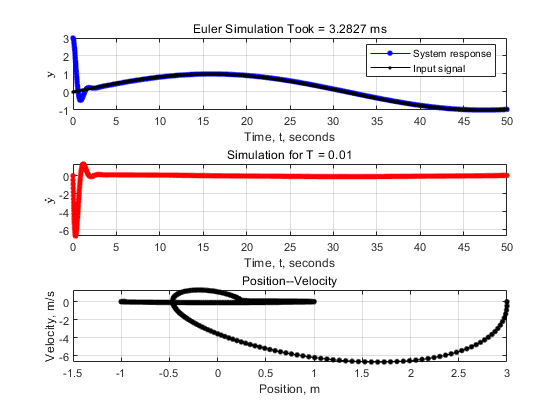

Time elapsed 3.283e+00 ms 
 


RESP = 1; 

N = round(5/T) + 1;
if RESP==0
    u = zeros(N,1);
elseif RESP ==1
[u,~] = gensig('sin',2*pi/0.1,50,0.01);
else
    u= 0;
end
figure(2);
clf;
f_sim(x0, T, u, RESP); 

Notice that the amplitude of the system remains unchanged relative to that of the input. Also, the the system response has a slight lead on the input signal. 

## PART 3: SIMULATE SYSTEM WITH ODE23

Simulate the natural response using ode23. 

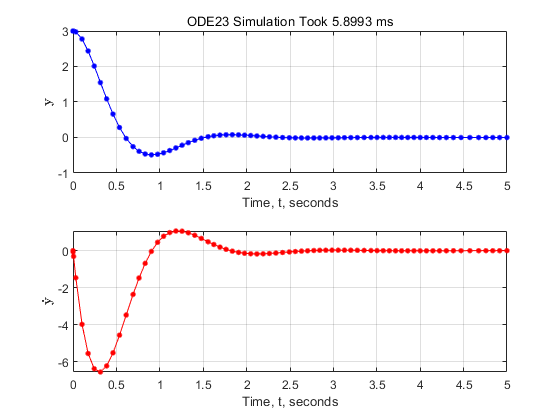

tspan = [0 5]; 
x0 = [3;0]; 
u = 0;
tic 

[t,y] = ode23(@(t,x) f(t,x,u), tspan, x0); 

tm = toc; 
tm = tm*1000; 

figure(3); 
clf; 

subplot(211)
plot(t,y(:,1), '.-b', 'MarkerSize', 12);
str = sprintf('ODE23 Simulation Took %g ms', tm); 
title (str)
xlabel('Time, t, seconds');
ylabel('$ \bf y$', 'Interpreter', 'latex');
grid on;

subplot(212)
plot(t,y(:,2), '.-r', 'MarkerSize', 12);
xlabel('Time, t, seconds');
ylabel('$ \bf \dot{y}$', 'Interpreter', 'latex');
grid on;